# Code to evualute the peak age of information

clc;
clear all;
% close all;

#### Parameters

**Spatial parameters**

r_inner=[0.1 0.3 0.7 1 2 3 4];%0.5:0.5:7;%inner circle radius in [m] jamalis2022low paragraph after Eq. (5)
r_outer=2*max(r_inner);%inner circle radius in [m] jamalis2022low paragraph after Eq. (5)
%IRS position
pos_ris = [0;0;0]; 
%AP position
pos_ap = [0.5;-2;0];
%MU's initial position
x_pos_UE=3;
pos_ue = [x_pos_UE;0;0];

**Mobility parameters**

v=1; % walking speed in [m/s] jamalis2022low paragraph after Eq. (5)
v_min_max=[0.5 1]; %minimum and maximum user's speed in m/s
total_v=100;
mean_stop=2;%stop time in seconds
%PDF for the user's velocity
v_vector=linspace(v_min_max(1),v_min_max(2),total_v);
f_V=1/(v_min_max(2)-v_min_max(1))*ones(1,length(v_vector));

**Transmission parameters**

fs=1.76*10^9;%sampling time of the receiver node
T_psdu=68.0364*10^(-6);
T_loc=T_psdu;%10^(-3);%localization time interval
T_IRS=T_psdu;%10^(-3);%IRS-updating time
T_d=(norm(pos_ap)+norm(pos_ue))/physconst('LightSpeed');%10^(-6);%transmission delay
fc = 60e9;%center frequency for transmissions
v_max=v*fc/physconst('LightSpeed');
T_coh=T_psdu;%sqrt(9/19*pi)*1/v_max;%coherence time
%the values 4459 is computed as ind.DMGHeader(2)
%with the IRS_802_11_ad code
T_ch=4352/fs;%T_coh/10;%channel estimation time
%the value 150592 is computed as ind.DMGData(2)-ind.DMGData(1)+1
%with the IRS_802_11_ad code
T_data=150592/fs;%50*10^(-3);%symbol time

**Simulation parameters**

delta_tau_j=0.5*10^(-4);%time granularity

**Plotting parameters**

color = {'#0072BD','#D95319','#EDB120','#7E2F8E','#77AC30','#4DBEEE','#A2142F'}; %list of colors from https://www.mathworks.com/help/matlab/creating_plots/specify-plot-colors.html
line_width=linspace(1,3,length(color));%specify the width for each line in the plot
marker={'-','-+','-d','-.','-x','-o','-s','-*','-|','-^'};% marker symbols are given at https://www.mathworks.com/help/matlab/creating_plots/create-line-plot-with-markers.html
marker_size=1:length(color);%specify the width for each marker in the plot
marker_indices=1:length(color);%specify the length between markers
fontsize=15;


### **RWP mobility model**

#### Evaluating $P_{r_\mathrm{out}}(T_\mathrm{in}<T_\mathrm{upd})$

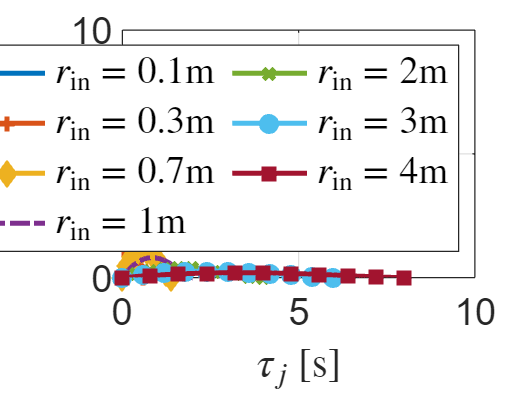

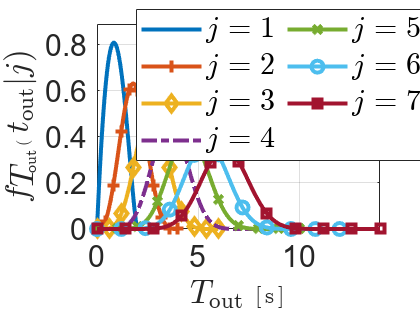

P_r_in_code_RWP

% P_r_in_code_RWP_stop_time

#### Evaluating $P_{r_\mathrm{in}}(T_\mathrm{out}<T_\mathrm{upd})$

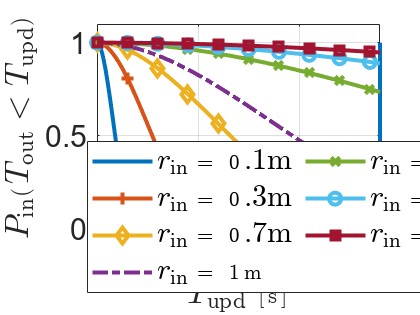

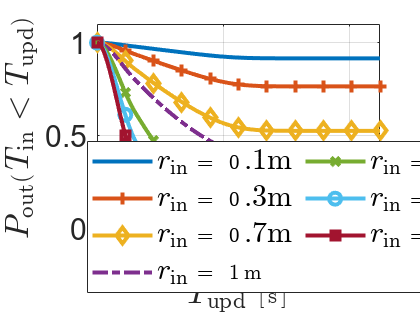

P_r_out_code_RWP

% P_r_out_code_RWP_stop_time


#### Evaluating the $\alpha_{k,j}$ parameter

$\alpha_{k,j}=\int_0^\infty{E_{k,j}(t)\mathrm{d}t}$,

where

$E_{11}(t)=1-u(t-T_\mathrm{setting})$,

$E_{12}(t)=\mathrm{Pr}_\mathrm{in}(t-T_\mathrm{setting}<T_\mathrm{upd})u(t-T_\mathrm{setting})$,

$E_{13}(t)=\mathrm{Pr}_\mathrm{out}(t-T_\mathrm{setting}<T_\mathrm{upd})u(t-T_\mathrm{setting})$,

and


$$T_\mathrm{setting}=T_\mathrm{loc}+T_\mathrm{IRS}$$


alpha_11=(T_loc+T_IRS)*ones(length(r_inner),length(tau));

[~,tau_length_in]=size(P_r_in);
[~,tau_length_out]=size(P_r_out);

tau_length=min(tau_length_in,tau_length_out);

alpha_12=cumtrapz(horzcat(zeros(length(r_inner),ceil((T_loc+T_IRS)/delta_tau_j)),P_r_in(:,1:tau_length)),2)*delta_tau_j;
alpha_13=cumtrapz(horzcat(zeros(length(r_inner),ceil((T_loc+T_IRS)/delta_tau_j)),1-P_r_in(:,1:tau_length)),2)*delta_tau_j;

% alpha_12=horzcat(zeros(length(r_inner),ceil((T_loc+T_IRS)/delta_tau_j)),cumtrapz(P_r_in(:,1:tau_length),2))*delta_tau_j;
% alpha_13=horzcat(zeros(length(r_inner),ceil((T_loc+T_IRS+r_inner(r)/v)/delta_tau_j)),cumtrapz(P_r_out(:,1:tau_length),2))*delta_tau_j;
% alpha_12=cumtrapz(horzcat(zeros(length(r_inner),ceil((T_loc+T_IRS)/delta_tau_j)),P_r_in(:,1:tau_length)),2)*delta_tau_j;
% alpha_13=cell(1,length(r_inner));
% for r=1:length(r_inner)
%     alpha_13{r}=cumtrapz(horzcat(zeros(1,ceil((T_loc+T_IRS+r_inner(r)/v)/delta_tau_j)),P_r_out(r,1:tau_length)),2)*delta_tau_j;
% end

#### Evaluating the proportion of time ($\pi_{j}$)

pi_vector=zeros(length(r_inner),length(tau),3);

for r=1:length(r_inner)
    for n=1:tau_length        
        pi_vector(r,n,:)=[alpha_11(r,n) alpha_12(r,n) alpha_13(r,n)]./sum([alpha_11(r,n) alpha_12(r,n) alpha_13(r,n)]);
    end
end

% for r=1:length(r_inner)
%     alpha_13_temp=alpha_13{r};
%     for n=1:tau_length
%         
%         pi_vector(r,n,:)=[alpha_11(r,n) alpha_12(r,n) alpha_13_temp(n)]./sum([alpha_11(r,n) alpha_12(r,n) alpha_13_temp(n)]);
% %           pi_vector(r,n,:)=[alpha_12(r,n) alpha_13(r,n)]./sum([alpha_12(r,n) alpha_13(r,n)]);
%     end
% end

**RWP: Plotting the proportion of time **$\pi$**vector**

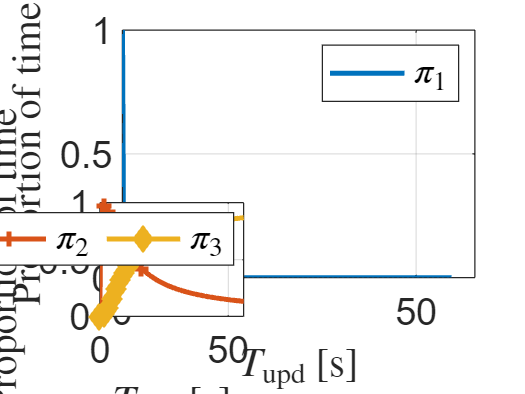

figure;
j=1;
r=length(r_inner);
plot(tau(1:tau_length),pi_vector(r,1:tau_length,j),marker{j},'Color',color{j},'LineWidth',2,...
        'MarkerEdgeColor',color{j},'MarkerFaceColor',color{j},'MarkerIndices',1:round(length(tau_j)/10):length(tau_j)); hold on;
legend({'$\pi_1$'},...
    'Location','northeast','NumColumns',2,'Interpreter',"latex",'FontSize',fontsize);% more properties on the legend at https://www.mathworks.com/help/matlab/ref/legend.html
grid on;
hold off %to close the canvas

xlabel('$T_\mathrm{upd}$ [s]','Interpreter','latex');
ylabel('Proportion of time','Interpreter','latex');
set(gca,'FontSize',fontsize);

p = get(gca, 'Position');
h = axes('Parent', gcf, 'Position', [p(1)+.06 p(2)+.06 p(3)-.5 p(4)-.5]);


for j=2:3
    plot(h,tau(1:tau_length),pi_vector(r,1:tau_length,j),marker{j},'Color',color{j},'LineWidth',2,...
        'MarkerEdgeColor',color{j},'MarkerFaceColor',color{j},'MarkerIndices',1:round(length(tau_j)/10):length(tau_j)); hold on;
end

grid on;
hold off %to close the canvas

step=1;
total_curves=2;
r=2:step:total_curves;
legend_text=cell(1,total_curves);
for m=1:total_curves
  legend_text{m}=strcat('$\pi_',num2str(m+1,2),'$');
end

legend({legend_text{:}},...
    'Location','northeast','NumColumns',2,'Interpreter',"latex",'FontSize',fontsize);% more properties on the legend at https://www.mathworks.com/help/matlab/ref/legend.html
grid on;
hold off %to close the canvas

xlabel('$T_\mathrm{upd}$ [s]','Interpreter','latex');
ylabel('Proportion of time','Interpreter','latex');
set(gca,'FontSize',fontsize);

% axis([0 tau_j(end) 0 1.1*max(f_tau_j{1})]);


**RWP: Plotting the proportion of time relative to **$\pi'_2=\frac{\pi_2}{1-\pi_1}$ and $\pi'_3=\frac{\pi_3}{1-\pi_1}$

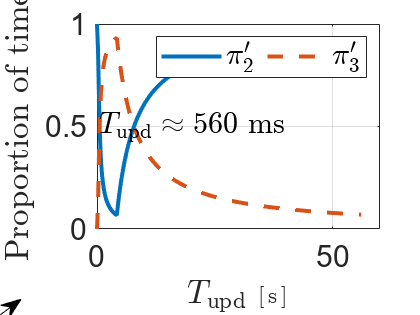

figure;

% pi_vector_2=pi_vector(:,:,2)+(1-pi_vector(:,:,3)).*pi_vector(:,:,1);
% pi_vector_3=pi_vector(:,:,3)+pi_vector(:,:,3).*pi_vector(:,:,1);

pi_vector_2=pi_vector(:,:,2)./(1-pi_vector(:,:,1));
pi_vector_3=pi_vector(:,:,3)./(1-pi_vector(:,:,1));

j=1;
r=2;


sample_shift=ceil((T_loc+T_IRS)/delta_tau_j)+1;
% plot(tau(sample_shift:tau_length),pi_vector(r,sample_shift:tau_length,2).*(tau(sample_shift:tau_length)+T_loc+T_IRS)./(tau(sample_shift:tau_length)),marker{j},'Color',color{j},'LineWidth',2,...
%         'MarkerEdgeColor',color{j},'MarkerFaceColor',color{j},'MarkerIndices',1:round(length(tau_j)/10):length(tau_j)); hold on;
plot(tau(sample_shift:tau_length),pi_vector_2(r,sample_shift:tau_length),'Color',color{j},'LineWidth',2,...
        'MarkerEdgeColor',color{j},'MarkerFaceColor',color{j},'MarkerIndices',1:round(length(tau_j)/10):length(tau_j)); hold on;
plot(tau(sample_shift:tau_length),pi_vector_3(r,sample_shift:tau_length),'--','Color',color{j+1},'LineWidth',2,...
        'MarkerEdgeColor',color{j+1},'MarkerFaceColor',color{j+1},'MarkerIndices',1:round(tau_length/10):tau_length);

% plot(tau(sample_shift:tau_length),pi_vector(r,sample_shift:tau_length,2)+pi_vector(r,sample_shift:tau_length,1).*pi_vector(r,sample_shift:tau_length,2)+(1-pi_vector(r,sample_shift:tau_length,2)).*pi_vector(r,sample_shift:tau_length,1)+pi_vector(r,sample_shift:tau_length,3),marker{j},'Color',color{j},'LineWidth',2,...
%         'MarkerEdgeColor',color{j},'MarkerFaceColor',color{j},'MarkerIndices',1:round(length(tau_j)/10):length(tau_j));

%plot(tau,pi_vector(r,:,j),marker{j},'Color',color{j},'LineWidth',2,...
%         'MarkerEdgeColor',color{j},'MarkerFaceColor',color{j},'MarkerIndices',1:round(length(tau_j)/10):length(tau_j)); hold on;

%Annotation
text(0.5,0.5,strcat('$T_\mathrm{upd}\approx 560$ ms'),'Interpreter','latex','FontSize',fontsize);
annotation('arrow', [0 0.05], [0 0.05]);

grid on;
hold off %to close the canvas

step=1;
total_curves=2;
r=2:step:total_curves;
legend_text=cell(1,total_curves);
for m=1:total_curves
  legend_text{m}=strcat('$\pi''_',num2str(m+1,2),'$');
end

legend({legend_text{:}},...
    'Location','northeast','NumColumns',2,'Interpreter',"latex",'FontSize',fontsize);% more properties on the legend at https://www.mathworks.com/help/matlab/ref/legend.html
grid on;
hold off %to close the canvas

xlabel('$T_\mathrm{upd}$ [s]','Interpreter','latex');
ylabel('Proportion of time','Interpreter','latex');
set(gca,'FontSize',fontsize);

% axis([0 tau_j(end) 0 1.1*max(f_tau_j{1})]);

#### RWP: Evaluating the PAoI


$$ \Delta^{(p)}=(T_d+T_\mathrm{Tx})+\left\lceil\frac{\pi_3T_\mathrm{upd}}{T_\mathrm{Tx}}\right\rceil T_\mathrm{Tx}\times\pi'_3,$$


and


$$T_\mathrm{Tx}=T_\mathrm{d}+\frac{T_\mathrm{d}}{T_\mathrm{upd}-T_\mathrm{ovh}}T_\mathrm{ovh}$$



$$T_\mathrm{ovh}=T_\mathrm{loc}+T_\mathrm{IRS}+c_hT_\mathrm{ch}$$



$$c_h=\frac{T_\mathrm{upd}-T_\mathrm{loc}+T_\mathrm{IRS}}{T_\mathrm{ch}+T_\mathrm{d}}$$


% T_loc=10^(-3);%localization time interval
% T_IRS=10^(-3);%IRS-updating time
% T_d=10^(-6);%transmission delay
% T_coh=10*10^(-3);%coherence time
% T_ch=10^(-3);%channel estimation time
% T_s=50*10^(-3);

%time interval for channel estimation
T_upd=T_IRS+T_loc+T_data:delta_tau_j:(T_IRS+T_loc+T_ch+T_data+(delta_tau_j)*(tau_length-1));

c_h=(T_upd-(T_IRS+T_loc))/(T_ch+T_data);

%delta_T_ch=(T_upd-((T_IRS+T_loc))/T_coh)*T_ch;%total of time to estimate the channel along T_upd 
%communication overhead
T_overhead=T_loc+T_IRS+c_h*T_ch;
%time interval for transmissions
%delta_T_Tx=T_upd-T_IRS-T_loc-delta_T_ch;
%transmission time
T_Tx=T_data+(T_data./(T_upd)).*T_overhead;
%transmission time
%T_Tx=T_coh+(T_coh)./(tau(1:tau_length)+delta_tau_j)*(T_loc+T_IRS);

%peak AoI
sample_shift=ceil((T_loc+T_IRS)/delta_tau_j);
PAoI_1=(T_d+T_Tx(1:tau_length)).*(pi_vector_2(:,1:tau_length));
PAoI_2=(T_d+T_Tx(1:tau_length)).*(pi_vector_3(:,1:tau_length))+...
    ((pi_vector(:,1:tau_length,3).*((sample_shift:sample_shift+tau_length-1)*delta_tau_j)./T_Tx(1:tau_length))).*T_Tx(1:tau_length).*pi_vector_3(:,1:tau_length);
PAoI_RWP=PAoI_1+PAoI_2;

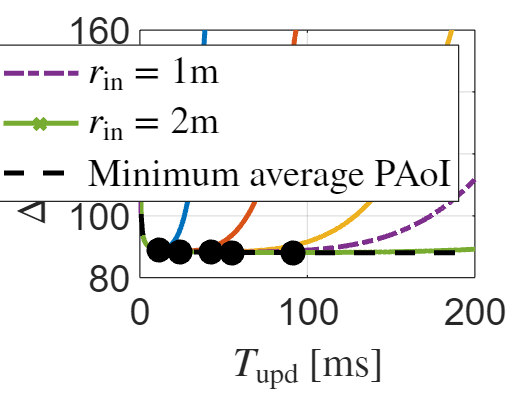


figure;
total_curves=5;
step=ceil(length(r_inner)/total_curves);
r=1:total_curves;%2:step:length(r_inner);
[~,tau_length]=size(PAoI_RWP(j,:));
%Plotting the average PAoI
for j=1:length(r)
     plot((0:tau_length-1)*delta_tau_j*10^3,PAoI_RWP(j,:)*10^6,marker{j},'LineWidth',2,...
         'MarkerIndices',1:round(tau_length/10):tau_length); hold on;
end

%Plotting the minimum PAoI
%time interval for channel estimation
plot((0:tau_length-1)*delta_tau_j*10^3,(T_Tx+T_d)*10^6,'--','LineWidth',2,'Color','black');

%Plotting the location of the minimum for the average PAoI
for j=1:length(r)
    [Min,idx]=min(PAoI_RWP(j,:));
    plot(tau(idx)*10^3,Min*10^(6),'o','LineWidth',2,'Color','black','MarkerFaceColor','black','MarkerSize',8);
end


%vertical line
% r=1;
% semilogy([r_inner(r)/v r_inner(r)/v],[0.01 10],'--','LineWidth',2,'Color','black');

xlabel('$T_\mathrm{upd}$ [ms]','Interpreter','latex');
ylabel('$\Delta^{(p)}$ [$\mu$s]','Interpreter','latex');
set(gca,'FontSize',fontsize)
grid on;

legend_text=cell(1,length(r)+1);
for m=1:length(r)
  legend_text{m}=strcat('$r_\mathrm{in}=',num2str(r_inner(r(m)),2),'$m');
end
legend_text{m+1}='Minimum average PAoI';

legend({legend_text{:}},...
    'Location','northeast','NumColumns',2,'Interpreter',"latex",'FontSize',fontsize);% more properties on the legend at https://www.mathworks.com/help/matlab/ref/legend.html
grid on;
hold off %to close the canvas
axis([0 200 80 160]);

figure;

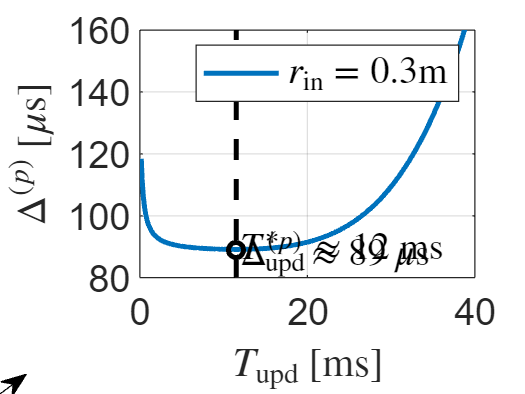

total_curves=1;
step=ceil(length(r_inner)/total_curves);
r=2;
[~,tau_length]=size(PAoI_RWP(j,:));
for j=1:length(r)
     plot((0:tau_length-1)*delta_tau_j*10^3,PAoI_RWP(j,:)*10^6,marker{j},'LineWidth',2,...
         'MarkerIndices',1:round(tau_length/10):tau_length); hold on;
end
%plotting the minimum
for j=1:length(r)
    [Min,idx]=min(PAoI_RWP(j,:));
    plot(tau(idx)*10^3,Min*10^6,'o','LineWidth',2,'Color','black');
end

%plotting the vertical line
plot([tau(idx) tau(idx)]*10^3,[0.1*Min 2*Min]*10^6,'--','LineWidth',2,'Color','black');

text(tau(idx)*10^3,Min*10^6,strcat('$\Delta^{(p)}\approx',num2str(Min*10^6,'%.0f'),'\, \mu$s'),'Interpreter','latex','FontSize',fontsize);
text(tau(idx)*10^3,Min*10^6,strcat('$T^*_\mathrm{upd}\approx',num2str((tau(idx))*10^3,'%.0f'),'$ ms'),'Interpreter','latex','FontSize',fontsize);
annotation('arrow', [0 0.05], [0 0.05]);

xlabel('$T_\mathrm{upd}$ [ms]','Interpreter','latex');
ylabel('$\Delta^{(p)}$ [$\mu$s]','Interpreter','latex');
set(gca,'FontSize',fontsize)
grid on;

legend_text=cell(1,length(r));
for m=1:length(r)
  legend_text{m}=strcat('$r_\mathrm{in}=',num2str(r_inner(r(m)),2),'$m');
end

legend({legend_text{:}},...
    'Location','northeast','NumColumns',2,'Interpreter',"latex",'FontSize',fontsize);% more properties on the legend at https://www.mathworks.com/help/matlab/ref/legend.html
grid on;
hold off %to close the canvas
axis([0 40 80 160]);

%evaluating T_ovh/T_data
T_overhead(find(T_upd>0.56,1))/(c_h(find(T_upd>0.56,1))*T_data)*100

ans = 2.9149

%evaluating the amount of frames for a given T_upd
tau(idx)/(T_data+T_ch+20*10^(-6))

ans = 106.4456

Evaluating the Minimum AoI

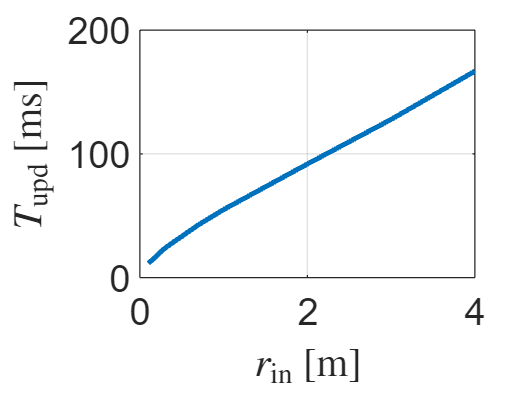

figure;

PAoI_RWP_Min=zeros(1,length(r_inner));
for r=1:length(r_inner)
    [Min,idx]=min(PAoI_RWP(r,:));
    PAoI_RWP_Min(r)=tau(idx);
end

plot(r_inner,PAoI_RWP_Min*10^3,'LineWidth',2);

ylabel('$T_\mathrm{upd}$ [ms]','Interpreter','latex');
xlabel('$r_\mathrm{in}$ [m]','Interpreter','latex');
set(gca,'FontSize',fontsize)
grid on;

### RWP with stop time

#### Evaluating $P_{r_\mathrm{out}}(T_\mathrm{in}<T_\mathrm{upd})$

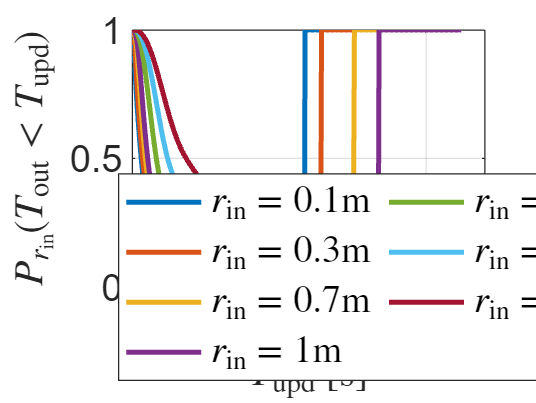

% P_r_in_code_RWP
P_r_in_code_RWP_stop_time

#### Evaluating $P_{r_\mathrm{in}}(T_\mathrm{out}<T_\mathrm{upd})$

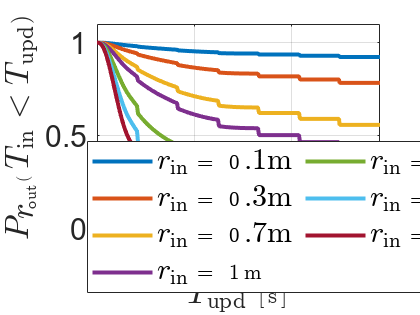

% P_r_out_code_RWP
P_r_out_code_RWP_stop_time

#### Evaluating the $\alpha_{k,j}$ parameter

$\alpha_{k,j}=\int_0^\infty{E_{k,j}(t)\mathrm{d}t}$,

where

$E_{11}(t)=1-u(t-T_\mathrm{setting})$,

$E_{12}(t)=\mathrm{Pr}_\mathrm{in}(t-T_\mathrm{setting}<T_\mathrm{upd})u(t-T_\mathrm{setting})$,

$E_{13}(t)=\mathrm{Pr}_\mathrm{out}(t-T_\mathrm{setting}<T_\mathrm{upd})u(t-T_\mathrm{setting})$,

and


$$T_\mathrm{setting}=T_\mathrm{loc}+T_\mathrm{IRS}$$


alpha_11=(T_loc+T_IRS)*ones(length(r_inner),length(tau));

[~,tau_length_in]=size(P_r_in);
[~,tau_length_out]=size(P_r_out);

tau_length=min(tau_length_in,tau_length_out);


% alpha_12=horzcat(zeros(length(r_inner),ceil((T_loc+T_IRS)/delta_tau_j)),cumtrapz(P_r_in(:,1:tau_length),2))*delta_tau_j;
% alpha_13=horzcat(zeros(length(r_inner),ceil((T_loc+T_IRS+r_inner(r)/v)/delta_tau_j)),cumtrapz(P_r_out(:,1:tau_length),2))*delta_tau_j;
alpha_12=cumtrapz(horzcat(zeros(length(r_inner),ceil((T_loc+T_IRS)/delta_tau_j)),P_r_in(:,1:tau_length)),2)*delta_tau_j;
alpha_13=cumtrapz(horzcat(zeros(length(r_inner),ceil((T_loc+T_IRS)/delta_tau_j)),1-P_r_in(:,1:tau_length)),2)*delta_tau_j;
% alpha_13=cell(1,length(r_inner));
% for r=1:length(r_inner)
% %     alpha_13{r}=cumtrapz(horzcat(zeros(1,ceil((T_loc+T_IRS)/delta_tau_j)),P_r_out(r,1:tau_length)),2)*delta_tau_j;
%     alpha_13{r}=cumtrapz(horzcat(zeros(1,ceil((T_loc+T_IRS+r_inner(r)/v+mean_stop)/delta_tau_j)),P_r_out(r,1:tau_length)),2)*delta_tau_j;
% end

#### Evaluating the proportion of time ($\pi_{j}$)

pi_vector=zeros(length(r_inner),length(tau),3);

for r=1:length(r_inner)
    for n=1:tau_length        
        pi_vector(r,n,:)=[alpha_11(r,n) alpha_12(r,n) alpha_13(r,n)]./sum([alpha_11(r,n) alpha_12(r,n) alpha_13(r,n)]);
    end
end

% for r=1:length(r_inner)
%     alpha_13_temp=alpha_13{r};
%     for n=1:tau_length
%         
%         pi_vector(r,n,:)=[alpha_11(r,n) alpha_12(r,n) alpha_13_temp(n)]./sum([alpha_11(r,n) alpha_12(r,n) alpha_13_temp(n)]);
% %           pi_vector(r,n,:)=[alpha_12(r,n) alpha_13(r,n)]./sum([alpha_12(r,n) alpha_13(r,n)]);
%     end
% end

**Plotting the proportion of time**

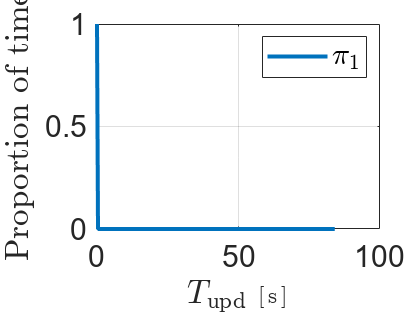

figure;
j=1;
r=length(r_inner);
plot(tau(1:tau_length),pi_vector(r,1:tau_length,j),marker{j},'Color',color{j},'LineWidth',2,...
        'MarkerEdgeColor',color{j},'MarkerFaceColor',color{j},'MarkerIndices',1:round(length(tau_j)/10):length(tau_j)); hold on;
legend({'$\pi_1$'},...
    'Location','northeast','NumColumns',2,'Interpreter',"latex",'FontSize',fontsize);% more properties on the legend at https://www.mathworks.com/help/matlab/ref/legend.html
grid on;
hold off %to close the canvas

xlabel('$T_\mathrm{upd}$ [s]','Interpreter','latex');
ylabel('Proportion of time','Interpreter','latex');
set(gca,'FontSize',fontsize);

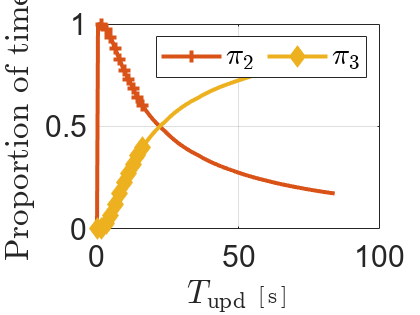


figure;
for j=2:3
    plot(tau(1:tau_length),pi_vector(r,1:tau_length,j),marker{j},'Color',color{j},'LineWidth',2,...
        'MarkerEdgeColor',color{j},'MarkerFaceColor',color{j},'MarkerIndices',1:round(length(tau_j)/10):length(tau_j)); hold on;
end

grid on;
hold off %to close the canvas

step=1;
total_curves=2;
r=2:step:total_curves;
legend_text=cell(1,total_curves);
for m=1:total_curves
  legend_text{m}=strcat('$\pi_',num2str(m+1,2),'$');
end

legend({legend_text{:}},...
    'Location','northeast','NumColumns',2,'Interpreter',"latex",'FontSize',fontsize);% more properties on the legend at https://www.mathworks.com/help/matlab/ref/legend.html
grid on;
hold off %to close the canvas

xlabel('$T_\mathrm{upd}$ [s]','Interpreter','latex');
ylabel('Proportion of time','Interpreter','latex');
set(gca,'FontSize',fontsize);

% axis([0 tau_j(end) 0 1.1*max(f_tau_j{1})]);


**Plotting the proportion of time relative to **$\pi'_2=\frac{\pi_2}{1-\pi_1}$ and $\pi'_3=\frac{\pi_3}{1-\pi_1}$

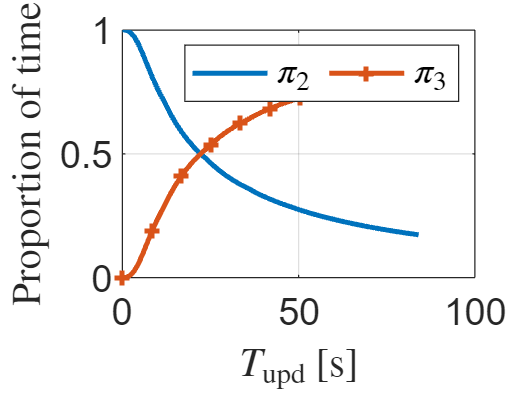

figure;

pi_vector_2=pi_vector(:,:,2)./(1-pi_vector(:,:,1));
pi_vector_3=pi_vector(:,:,3)./(1-pi_vector(:,:,1));

j=1;
r=length(r_inner);


sample_shift=ceil((T_loc+T_IRS)/delta_tau_j)+1;
% plot(tau(sample_shift:tau_length),pi_vector(r,sample_shift:tau_length,2).*(tau(sample_shift:tau_length)+T_loc+T_IRS)./(tau(sample_shift:tau_length)),marker{j},'Color',color{j},'LineWidth',2,...
%         'MarkerEdgeColor',color{j},'MarkerFaceColor',color{j},'MarkerIndices',1:round(length(tau_j)/10):length(tau_j)); hold on;
plot(tau(sample_shift:tau_length),pi_vector_2(r,sample_shift:tau_length),marker{j},'Color',color{j},'LineWidth',2,...
        'MarkerEdgeColor',color{j},'MarkerFaceColor',color{j},'MarkerIndices',1:round(length(tau_j)/10):length(tau_j)); hold on;
plot(tau(sample_shift:tau_length),pi_vector_3(r,sample_shift:tau_length),marker{j+1},'Color',color{j+1},'LineWidth',2,...
        'MarkerEdgeColor',color{j+1},'MarkerFaceColor',color{j+1},'MarkerIndices',1:round(tau_length/10):tau_length);

% plot(tau(sample_shift:tau_length),pi_vector(r,sample_shift:tau_length,2)+pi_vector(r,sample_shift:tau_length,1).*pi_vector(r,sample_shift:tau_length,2)+(1-pi_vector(r,sample_shift:tau_length,2)).*pi_vector(r,sample_shift:tau_length,1)+pi_vector(r,sample_shift:tau_length,3),marker{j},'Color',color{j},'LineWidth',2,...
%         'MarkerEdgeColor',color{j},'MarkerFaceColor',color{j},'MarkerIndices',1:round(length(tau_j)/10):length(tau_j));

%plot(tau,pi_vector(r,:,j),marker{j},'Color',color{j},'LineWidth',2,...
%         'MarkerEdgeColor',color{j},'MarkerFaceColor',color{j},'MarkerIndices',1:round(length(tau_j)/10):length(tau_j)); hold on;


grid on;
hold off %to close the canvas

step=1;
total_curves=2;
r=2:step:total_curves;
legend_text=cell(1,total_curves);
for m=1:total_curves
  legend_text{m}=strcat('$\pi_',num2str(m+1,2),'$');
end

legend({legend_text{:}},...
    'Location','northeast','NumColumns',2,'Interpreter',"latex",'FontSize',fontsize);% more properties on the legend at https://www.mathworks.com/help/matlab/ref/legend.html
grid on;
hold off %to close the canvas

xlabel('$T_\mathrm{upd}$ [s]','Interpreter','latex');
ylabel('Proportion of time','Interpreter','latex');
set(gca,'FontSize',fontsize);

% axis([0 tau_j(end) 0 1.1*max(f_tau_j{1})]);

#### Stop Time: Evaluating the PAoI


$$ \Delta^{(p)}=(T_d+T_\mathrm{Tx})+\left\lceil\frac{\pi_3T_\mathrm{upd}}{T_\mathrm{Tx}}\right\rceil T_\mathrm{Tx}\times\pi'_3,$$


and


$$T_\mathrm{Tx}=T_\mathrm{s}+\frac{T_\mathrm{s}}{T_\mathrm{upd}-T_\mathrm{ovh}}T_\mathrm{ovh}$$


% T_loc=10^(-3);%localization time interval
% T_IRS=10^(-3);%IRS-updating time
% T_d=10^(-6);%transmission delay
% T_coh=10*10^(-3);%coherence time
% T_ch=10^(-3);%channel estimation time
% T_s=50*10^(-3);

%time interval for channel estimation
T_upd=T_IRS+T_loc+T_ch+T_data:delta_tau_j:(T_IRS+T_loc+T_ch+T_data+(delta_tau_j)*(tau_length-1));
delta_T_ch=(T_upd/T_coh)*T_ch;
%communication overhead
T_overhead=T_loc+T_IRS+delta_T_ch;
%time interval for transmissions
delta_T_Tx=T_upd-T_IRS-T_loc-delta_T_ch;
%transmission time
T_Tx=T_data+(T_data./delta_T_Tx).*T_overhead;
%transmission time
%T_Tx=T_coh+(T_coh)./(tau(1:tau_length)+delta_tau_j)*(T_loc+T_IRS);

%peak AoI
sample_shift=ceil((T_loc+T_IRS)/delta_tau_j);
PAoI_1=(T_d+T_Tx(1:tau_length)).*(pi_vector_2(:,1:tau_length));
PAoI_2=(T_d+T_Tx(1:tau_length)).*(pi_vector_3(:,1:tau_length))+...
    ((pi_vector(:,1:tau_length,3).*((sample_shift:sample_shift+tau_length-1)*delta_tau_j)./T_Tx(1:tau_length))).*T_Tx(1:tau_length).*pi_vector_3(:,1:tau_length);
PAoI_RWP_StopTime=PAoI_1+PAoI_2;

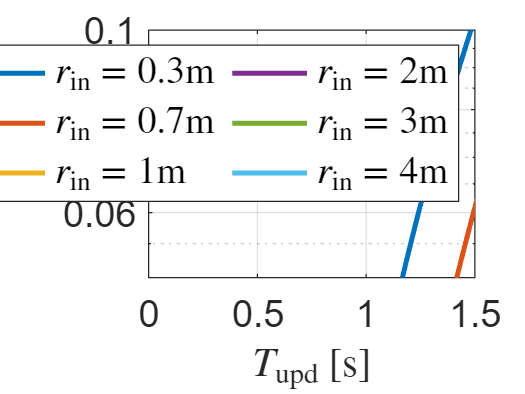

figure;
total_curves=7;
step=ceil(length(r_inner)/total_curves);
r=2:step:length(r_inner);
for j=1:length(r)
    
    
%     PAoI_1=(T_d+T_Tx).*(pi_vector(r,sample_shift:tau_length,2));
%     PAoI_2=(T_d+T_Tx).*(pi_vector(r,sample_shift:tau_length,3))+...
%         ceil(pi_vector(r,sample_shift:tau_length,3).*(tau(1:tau_length))./T_Tx).*T_Tx.*pi_vector(r,sample_shift:tau_length,3);
    % PAoI_2=ceil(pi_vector(r,sample_shift:tau_length,3).*(tau(1:tau_length)+T_coh)./T_Tx);%.*T_Tx.*pi_vector(r,sample_shift:tau_length,3);

    % plot(tau(1:tau_length),PAoI_1(1,:),'LineWidth',2); hold on;
%     plot(tau(1:tau_length),PAoI_1(1,:)+PAoI_2(1,:),'LineWidth',2); hold on;
    semilogy((0:length(PAoI_RWP_StopTime(j,:))-1)*delta_tau_j,PAoI_RWP_StopTime(j,:),'LineWidth',2); hold on;
%     semilogy(tau(1:tau_length)+T_IRS+T_loc+T_coh,PAoI_1(1,:)+PAoI_2(1,:),'LineWidth',2); hold on;
end

for j=1:length(r)
    [Min,idx]=min(PAoI_RWP_StopTime(j,:));
    semilogy(tau(idx)+T_IRS+T_loc+T_coh,Min,'o','LineWidth',2,'Color','black');
end


%vertical line
% r=1;
% semilogy([r_inner(r)/v r_inner(r)/v],[0.01 10],'--','LineWidth',2,'Color','black');

xlabel('$T_\mathrm{upd}$ [s]','Interpreter','latex');
ylabel('$\Delta^{(p)}$','Interpreter','latex');
set(gca,'FontSize',fontsize)
grid on;

legend_text=cell(1,length(r));
for m=1:length(r)
  legend_text{m}=strcat('$r_\mathrm{in}=',num2str(r_inner(r(m)),2),'$m');
end

legend({legend_text{:}},...
    'Location','northeast','NumColumns',2,'Interpreter',"latex",'FontSize',fontsize);% more properties on the legend at https://www.mathworks.com/help/matlab/ref/legend.html
grid on;
hold off %to close the canvas

axis([0 1.5 0.05 10^(-1)]);

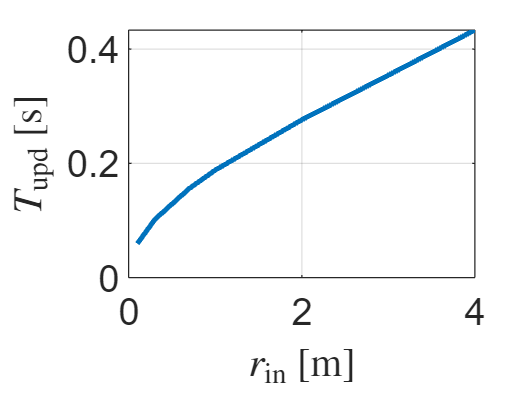

figure;

PAoI_RWP_StopTime_Min=zeros(1,length(r_inner));
for r=1:length(r_inner)
    [Min,idx]=min(PAoI_RWP_StopTime(r,:));
    PAoI_RWP_StopTime_Min(r)=tau(idx);
end

plot(r_inner,PAoI_RWP_StopTime_Min*100,'LineWidth',2);

ylabel('$T_\mathrm{upd}$ [ms]','Interpreter','latex');
xlabel('$r_\mathrm{in}$ [m]','Interpreter','latex');
set(gca,'FontSize',fontsize)
grid on;

### RWP with random velocity

#### Evaluating $P_{r_\mathrm{out}}(T_\mathrm{in}<T_\mathrm{upd})$

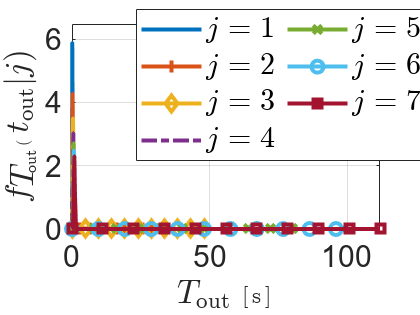

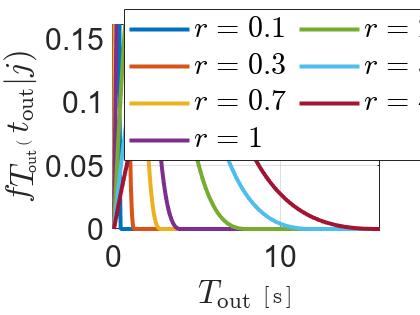

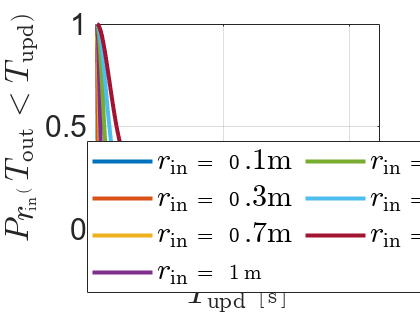

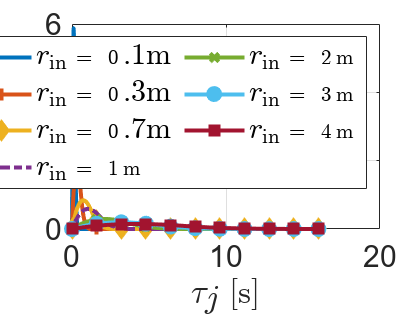

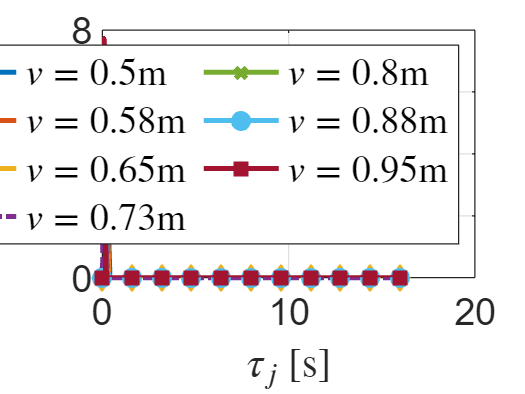

% P_r_in_code_RWP
% P_r_in_code_RWP_stop_time
P_r_in_code_RWP_random_speed

#### Evaluating $P_{r_\mathrm{in}}(T_\mathrm{out}<T_\mathrm{upd})$

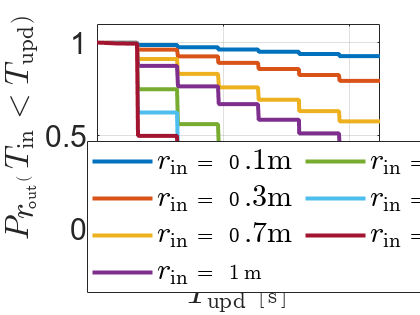

% P_r_out_code_RWP
% P_r_out_code_RWP_stop_time
P_r_out_code_RWP_ramdon_speed

#### Evaluating the $\alpha_{k,j}$ parameter

$\alpha_{k,j}=\int_0^\infty{E_{k,j}(t)\mathrm{d}t}$,

where

$E_{11}(t)=1-u(t-T_\mathrm{setting})$,

$E_{12}(t)=\mathrm{Pr}_\mathrm{in}(t-T_\mathrm{setting}<T_\mathrm{upd})u(t-T_\mathrm{setting})$,

$E_{13}(t)=\mathrm{Pr}_\mathrm{out}(t-T_\mathrm{setting}<T_\mathrm{upd})u(t-T_\mathrm{setting})$,

and


$$T_\mathrm{setting}=T_\mathrm{loc}+T_\mathrm{IRS}$$


alpha_11=(T_loc+T_IRS)*ones(length(r_inner),length(tau));


[~,tau_length_in]=size(P_r_in);
[~,tau_length_out]=size(P_r_out);

tau_length=min(tau_length_in,tau_length_out);

alpha_12=cumtrapz(horzcat(zeros(length(r_inner),ceil((T_loc+T_IRS)/delta_tau_j)),P_r_in(:,1:tau_length)),2)*delta_tau_j;
alpha_13=cumtrapz(horzcat(zeros(length(r_inner),ceil((T_loc+T_IRS)/delta_tau_j)),1-P_r_in(:,1:tau_length)),2)*delta_tau_j;


#### Evaluating the proportion of time ($\pi_{j}$)

pi_vector=zeros(length(r_inner),length(tau),3);

for r=1:length(r_inner)
    for n=1:tau_length        
        pi_vector(r,n,:)=[alpha_11(r,n) alpha_12(r,n) alpha_13(r,n)]./sum([alpha_11(r,n) alpha_12(r,n) alpha_13(r,n)]);
    end
end


**Plotting the proportion of time**

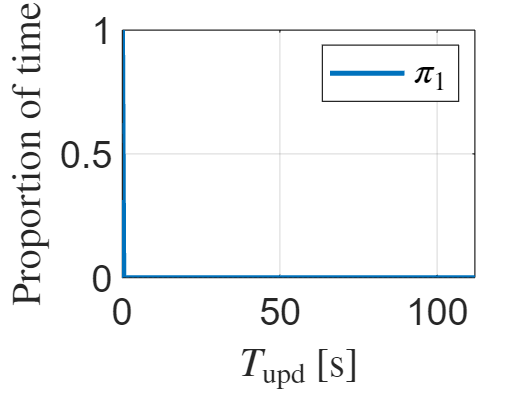

figure;
j=1;
r=length(r_inner);
plot(tau(1:tau_length),pi_vector(r,1:tau_length,j),marker{j},'Color',color{j},'LineWidth',2,...
        'MarkerEdgeColor',color{j},'MarkerFaceColor',color{j},'MarkerIndices',1:round(length(tau_j)/10):length(tau_j)); hold on;
legend({'$\pi_1$'},...
    'Location','northeast','NumColumns',2,'Interpreter',"latex",'FontSize',fontsize);% more properties on the legend at https://www.mathworks.com/help/matlab/ref/legend.html
grid on;
hold off %to close the canvas

xlabel('$T_\mathrm{upd}$ [s]','Interpreter','latex');
ylabel('Proportion of time','Interpreter','latex');
set(gca,'FontSize',fontsize);

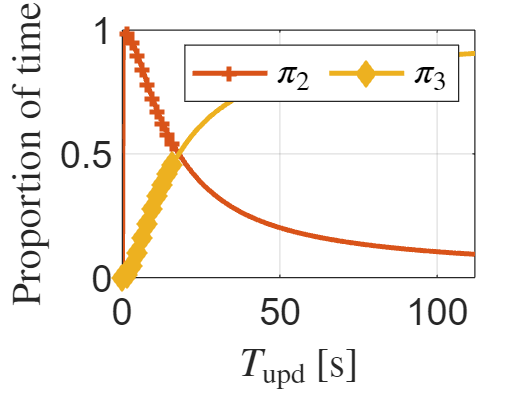


figure;
for j=2:3
    plot(tau(1:tau_length),pi_vector(r,1:tau_length,j),marker{j},'Color',color{j},'LineWidth',2,...
        'MarkerEdgeColor',color{j},'MarkerFaceColor',color{j},'MarkerIndices',1:round(length(tau_j)/10):length(tau_j)); hold on;
end

grid on;
hold off %to close the canvas

step=1;
total_curves=2;
r=2:step:total_curves;
legend_text=cell(1,total_curves);
for m=1:total_curves
  legend_text{m}=strcat('$\pi_',num2str(m+1,2),'$');
end

legend({legend_text{:}},...
    'Location','northeast','NumColumns',2,'Interpreter',"latex",'FontSize',fontsize);% more properties on the legend at https://www.mathworks.com/help/matlab/ref/legend.html
grid on;
hold off %to close the canvas

xlabel('$T_\mathrm{upd}$ [s]','Interpreter','latex');
ylabel('Proportion of time','Interpreter','latex');
set(gca,'FontSize',fontsize);

% axis([0 tau_j(end) 0 1.1*max(f_tau_j{1})]);


**Plotting the proportion of time relative to **$\pi'_2=\frac{\pi_2}{1-\pi_1}$ and $\pi'_3=\frac{\pi_3}{1-\pi_1}$

figure;

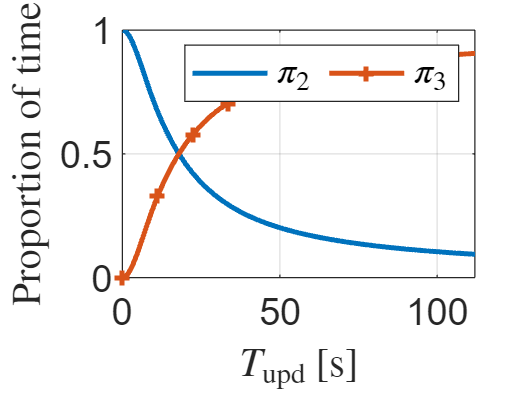


pi_vector_2=pi_vector(:,:,2)./(1-pi_vector(:,:,1));
pi_vector_3=pi_vector(:,:,3)./(1-pi_vector(:,:,1));

j=1;
r=length(r_inner);


sample_shift=ceil((T_loc+T_IRS)/delta_tau_j)+1;
plot(tau(sample_shift:tau_length),pi_vector_2(r,sample_shift:tau_length),marker{j},'Color',color{j},'LineWidth',2,...
        'MarkerEdgeColor',color{j},'MarkerFaceColor',color{j},'MarkerIndices',1:round(length(tau_j)/10):length(tau_j)); hold on;
plot(tau(sample_shift:tau_length),pi_vector_3(r,sample_shift:tau_length),marker{j+1},'Color',color{j+1},'LineWidth',2,...
        'MarkerEdgeColor',color{j+1},'MarkerFaceColor',color{j+1},'MarkerIndices',1:round(tau_length/10):tau_length);


grid on;
hold off %to close the canvas

step=1;
total_curves=2;
r=2:step:total_curves;
legend_text=cell(1,total_curves);
for m=1:total_curves
  legend_text{m}=strcat('$\pi_',num2str(m+1,2),'$');
end

legend({legend_text{:}},...
    'Location','northeast','NumColumns',2,'Interpreter',"latex",'FontSize',fontsize);% more properties on the legend at https://www.mathworks.com/help/matlab/ref/legend.html
grid on;
hold off %to close the canvas

xlabel('$T_\mathrm{upd}$ [s]','Interpreter','latex');
ylabel('Proportion of time','Interpreter','latex');
set(gca,'FontSize',fontsize);

% axis([0 tau_j(end) 0 1.1*max(f_tau_j{1})]);

#### Random Velocity: Evaluating the PAoI


$$ \Delta^{(p)}=(T_d+T_\mathrm{Tx})+\left\lceil\frac{\pi_3T_\mathrm{upd}}{T_\mathrm{Tx}}\right\rceil T_\mathrm{Tx}\times\pi'_3,$$


and


$$T_\mathrm{Tx}=T_\mathrm{s}+\frac{T_\mathrm{s}}{T_\mathrm{upd}-T_\mathrm{ovh}}T_\mathrm{ovh}$$


% T_loc=10^(-3);%localization time interval
% T_IRS=10^(-3);%IRS-updating time
% T_d=10^(-6);%transmission delay
% T_coh=10*10^(-3);%coherence time
% T_ch=10^(-3);%channel estimation time
% T_s=50*10^(-3);

%time interval for channel estimation
T_upd=T_IRS+T_loc+T_ch+T_data:delta_tau_j:(T_IRS+T_loc+T_ch+T_data+(delta_tau_j)*(tau_length-1));

delta_T_ch=(T_upd/T_coh)*T_ch;
%communication overhead
T_overhead=T_loc+T_IRS+delta_T_ch;
%time interval for transmissions
delta_T_Tx=T_upd-T_IRS-T_loc-delta_T_ch;
%transmission time
T_Tx=T_data+(T_data./delta_T_Tx).*T_overhead;
%transmission time
%T_Tx=T_coh+(T_coh)./(tau(1:tau_length)+delta_tau_j)*(T_loc+T_IRS);

%peak AoI
sample_shift=ceil((T_loc+T_IRS)/delta_tau_j);
PAoI_1=(T_d+T_Tx(1:tau_length)).*(pi_vector_2(:,1:tau_length));
PAoI_2=(T_d+T_Tx(1:tau_length)).*(pi_vector_3(:,1:tau_length))+...
    ((pi_vector_3(:,1:tau_length).*((sample_shift:sample_shift+tau_length-1)*delta_tau_j)./T_Tx(1:tau_length))).*T_Tx(1:tau_length).*pi_vector_3(:,1:tau_length);
PAoI_RWP_RandomVelocity=PAoI_1+PAoI_2;

**Plotting the PAoI**

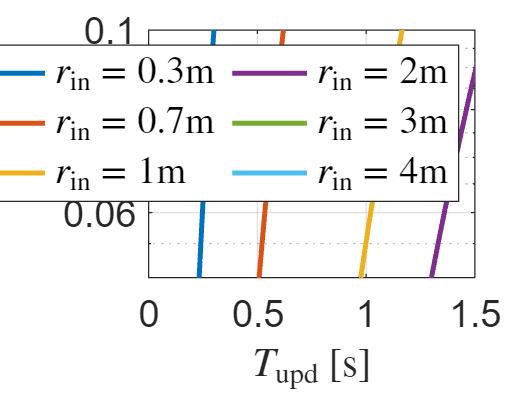

figure;
total_curves=7;
step=ceil(length(r_inner)/total_curves);
r=2:step:length(r_inner);
for j=1:length(r)
    semilogy((0:length(PAoI_RWP_RandomVelocity(j,:))-1)*delta_tau_j,PAoI_RWP_RandomVelocity(j,:),'LineWidth',2); hold on;
end

for j=1:length(r)
    [Min,idx]=min(PAoI_RWP_RandomVelocity(j,:));
    semilogy(tau(idx)+T_IRS+T_loc+T_coh,Min,'o','LineWidth',2,'Color','black');
end


%vertical line
% r=1;
% semilogy([r_inner(r)/v r_inner(r)/v],[0.01 10],'--','LineWidth',2,'Color','black');

xlabel('$T_\mathrm{upd}$ [s]','Interpreter','latex');
ylabel('$\Delta^{(p)}$','Interpreter','latex');
set(gca,'FontSize',fontsize)
grid on;

legend_text=cell(1,length(r));
for m=1:length(r)
  legend_text{m}=strcat('$r_\mathrm{in}=',num2str(r_inner(r(m)),2),'$m');
end

legend({legend_text{:}},...
    'Location','northeast','NumColumns',2,'Interpreter',"latex",'FontSize',fontsize);% more properties on the legend at https://www.mathworks.com/help/matlab/ref/legend.html
grid on;
hold off %to close the canvas

axis([0 1.5 0.05 10^(-1)]);

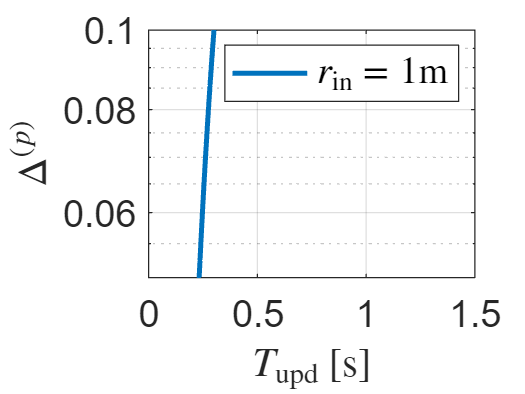

figure;
total_curves=1;
step=ceil(length(r_inner)/total_curves);
r=4;
for j=1:length(r)
    semilogy((0:length(PAoI_RWP_RandomVelocity(j,:))-1)*delta_tau_j,PAoI_RWP_RandomVelocity(j,:),'LineWidth',2); hold on;
end

for j=1:length(r)
    [Min,idx]=min(PAoI_RWP_RandomVelocity(j,:));
    semilogy(tau(idx)+T_IRS+T_loc+T_coh,Min,'o','LineWidth',2,'Color','black');
end


%vertical line
% r=1;
% semilogy([r_inner(r)/v r_inner(r)/v],[0.01 10],'--','LineWidth',2,'Color','black');

xlabel('$T_\mathrm{upd}$ [s]','Interpreter','latex');
ylabel('$\Delta^{(p)}$','Interpreter','latex');
set(gca,'FontSize',fontsize)
grid on;

legend_text=cell(1,length(r));
for m=1:length(r)
  legend_text{m}=strcat('$r_\mathrm{in}=',num2str(r_inner(r(m)),2),'$m');
end

legend({legend_text{:}},...
    'Location','northeast','NumColumns',2,'Interpreter',"latex",'FontSize',fontsize);% more properties on the legend at https://www.mathworks.com/help/matlab/ref/legend.html
grid on;
hold off %to close the canvas

axis([0 1.5 0.05 10^(-1)]);

**Plotting the minimum PAoI vs radius**

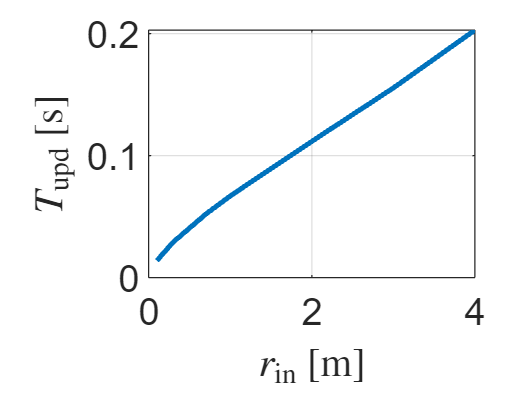

figure;

PAoI_RWP_RandomVelocity_Min=zeros(1,length(r_inner));
for r=1:length(r_inner)
    [Min,idx]=min(PAoI_RWP_RandomVelocity(r,:));
    PAoI_RWP_RandomVelocity_Min(r)=tau(idx);
end

plot(r_inner,PAoI_RWP_RandomVelocity_Min*100,'LineWidth',2);

%vertical line
% r=1;
% semilogy([r_inner(r)/v r_inner(r)/v],[0.01 10],'--','LineWidth',2,'Color','black');

ylabel('$T_\mathrm{upd}$ [ms]','Interpreter','latex');
xlabel('$r_\mathrm{in}$ [m]','Interpreter','latex');
set(gca,'FontSize',fontsize)
grid on;


% legend_text=cell(1,length(r));
% for m=1:length(r)
%   legend_text{m}=strcat('$r_\mathrm{in}=',num2str(r_inner(r(m)),2),'$m');
% end
% 
% legend({legend_text{:}},...
%     'Location','northeast','NumColumns',2,'Interpreter',"latex",'FontSize',fontsize);% more properties on the legend at https://www.mathworks.com/help/matlab/ref/legend.html
% grid on;
% hold off %to close the canvas

% axis([0 1.5 0.05 10^(-1)]);

**Plotting T_upd vs r for the various mobility models**

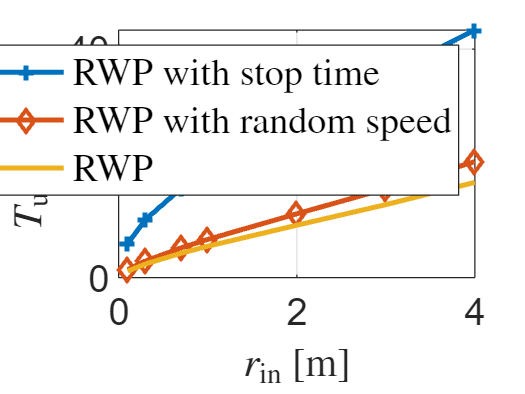

figure;
plot(r_inner,PAoI_RWP_StopTime_Min*100,marker{2},'LineWidth',2);hold on; grid on;
plot(r_inner,PAoI_RWP_RandomVelocity_Min*100,marker{3},'LineWidth',2);
plot(r_inner,PAoI_RWP_Min*100,'LineWidth',2); 

legend({'RWP with stop time','RWP with random speed','RWP'},...
    'Location','northeast','NumColumns',1,'Interpreter',"latex",'FontSize',fontsize);% more properties on the legend at https://www.mathworks.com/help/matlab/ref/legend.html
grid on;
hold off %to close the canvas

ylabel('$T_\mathrm{upd}$ [ms]','Interpreter','latex');
xlabel('$r_\mathrm{in}$ [m]','Interpreter','latex');
set(gca,'FontSize',fontsize)
grid on;

% T_loc=10^(-3);%localization time interval
% T_IRS=10^(-3);%IRS-updating time
% T_d=10^(-6);%transmission delay
% T_coh=10*10^(-3);%coherence time
% T_ch=10^(-3);%channel estimation time
% 
% T_s=50*10^(-3);
% 
% T_upd=linspace(T_IRS+T_loc+T_ch+T_s,1,1000);
% delta_T_ch=(T_upd/T_coh)*T_ch;
% T_overhead=T_loc+T_IRS+delta_T_ch;
% delta_T_Tx=T_upd-T_IRS-T_loc-delta_T_ch;
% T_Tx=T_s+(T_s./delta_T_Tx).*T_overhead;
% figure;
% plot(T_upd,T_Tx)